## Transistor circuits

ELABorate can handle transistors by modelling them using an appropriate set of linear elements.

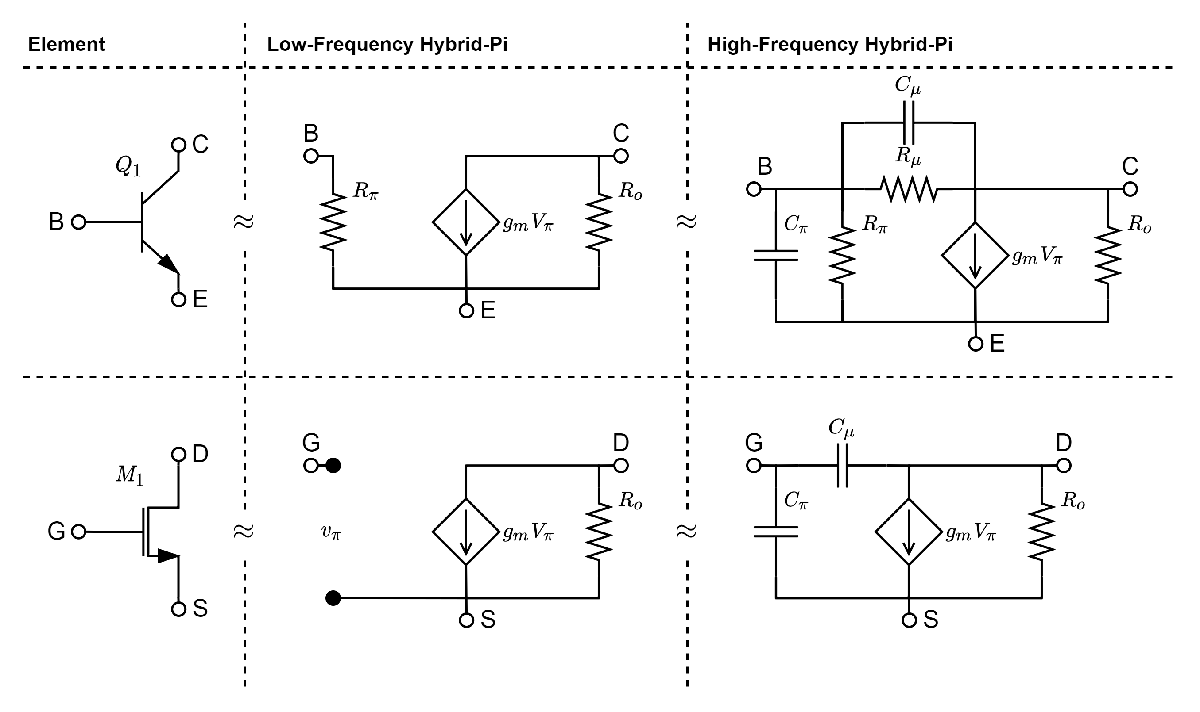

### 1. BJTs

We start by loading in a circuit containing a BJT. In this case, it's a simple common-source amplifier with biasing. The circuit is from Microelectronic Circuits 7th edition, page 410. 

circuit = Circuit('circuits/bjt_cs_amp.txt');
circuit.list

ans =     'V_BB 1 0 DC V_BB
     V_CC 5 0 DC V_CC
     V_i 2 1 AC V_i
     R_B 2 3 R_B
     R_C 4 5 R_C
     Q_1 3 4 0 beta_Q_1
     '


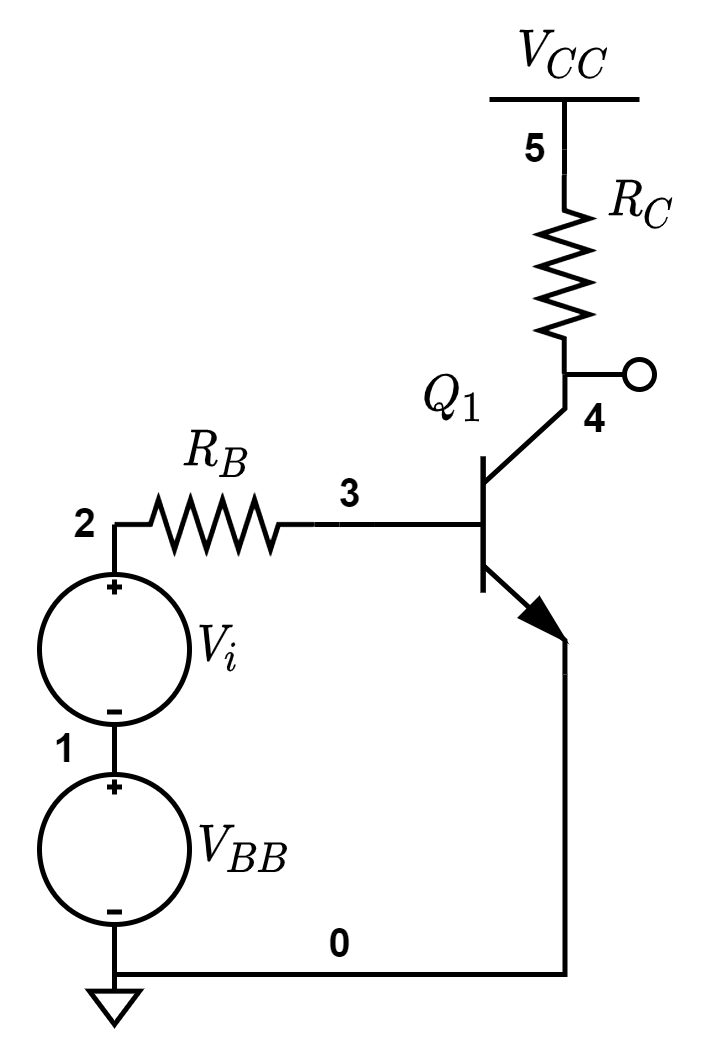

Typically, when analyzing such circuits, we split up the analysis into a DC-part and an AC-part. To find the DC-equivalent of the circuit above, one can simply call the `dc_eq` function (short for *direct-current-equivalent*). This function uses lower-level functions such as `short`, `open` and `clean` to modify the given circuit into its DC-equivalent.

ELAB.dc_eq(circuit);
circuit.list

ans =     'V_BB 1 0 DC V_BB
     V_CC 4 0 DC V_CC
     R_B 1 2 R_B
     R_C 3 4 R_C
     Q_1 2 3 0 beta_Q_1
     '


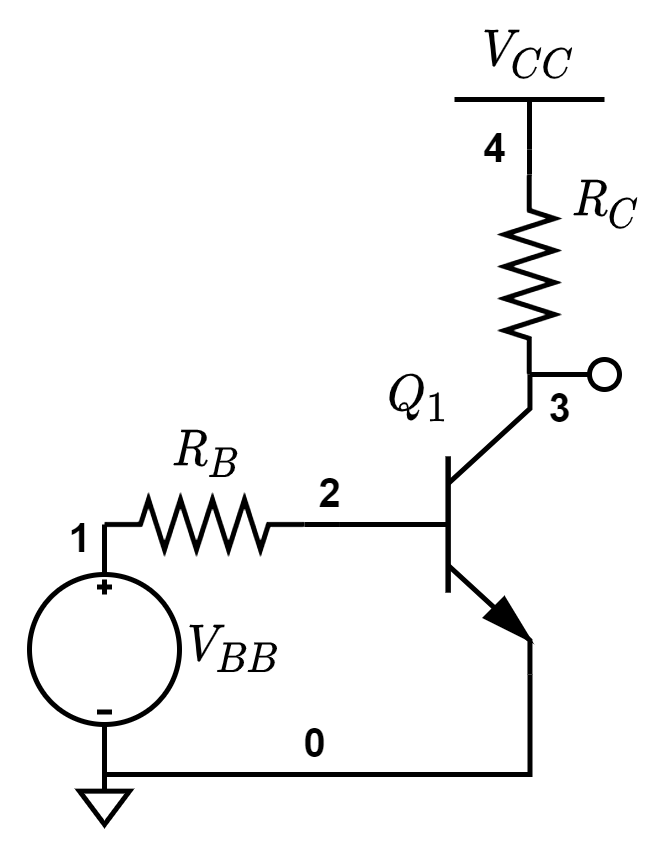

Similarly, the program can convert the given circuit into its AC-equivalent.

circuit = Circuit('circuits/bjt_cs_amp.txt');
ELAB.ac_eq(circuit);
circuit.list

ans =     'V_i 1 0 AC V_i
     R_B 1 2 R_B
     R_C 3 0 R_C
     Q_1 2 3 0 beta_Q_1
     '


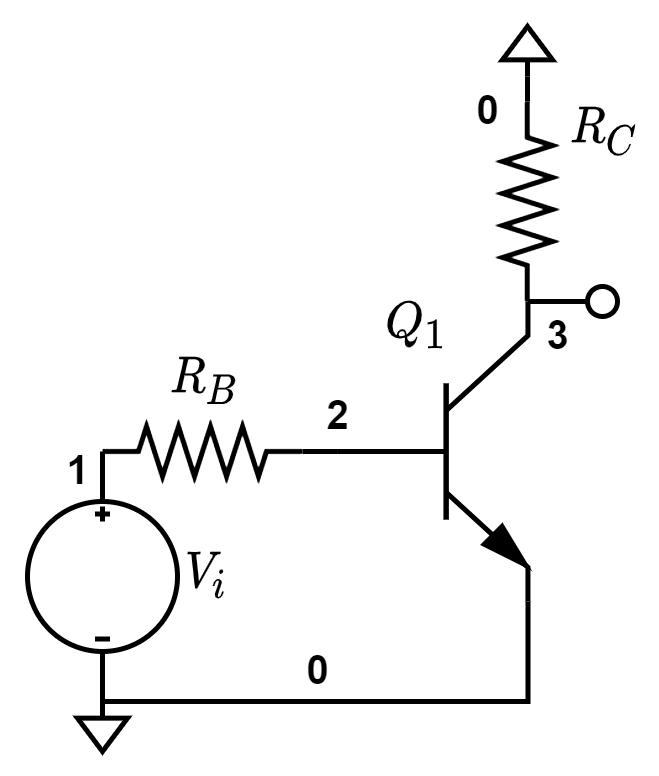

From the AC-equivalent, you can model the transistor as linear elements, using the `hpi` (hybrid-pi) function, which can either assume the circuit will operate in low-frequency "`lf`" or high-frequency "`hf`". We can use the `clone` function to preserve the AC-equivalent.

circuit = Circuit('circuits/bjt_cs_amp.txt');
ELAB.hybrid_pi(circuit,'lf');
circuit.list

ans =     'V_i 1 0 AC V_i
     R_B 1 2 R_B
     R_C 3 0 R_C
     R_pi_Q_1 2 0 R_pi_Q_1
     R_o_Q_1 3 0 R_o_Q_1
     G_Q_1 3 0 0 2 G_Q_1
     '


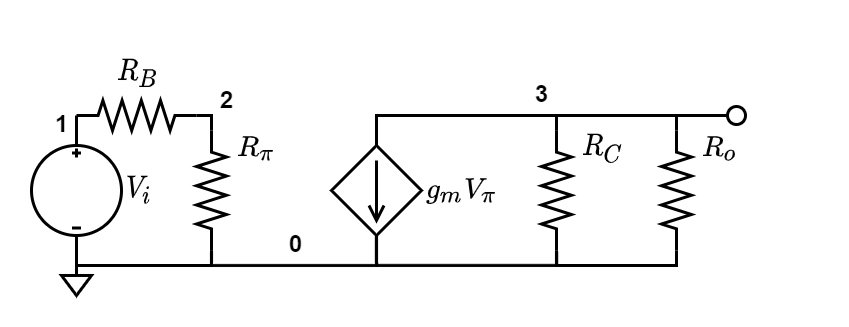

Of course we may also simplify this circuit. The simplifier takes into account that a dependent source relies on the voltage across $R_{\pi }$ and so does not simplify the series $R_B +R_{\pi }$.

ELAB.simplify(circuit);
circuit.list

ans =     'V_i 1 0 AC V_i
     R_B 1 2 R_B
     R_pi_Q_1 2 0 R_pi_Q_1
     R_eq1 3 0 (R_C*R_o_Q_1)/(R_C+R_o_Q_1)
     G_Q_1 3 0 0 2 G_Q_1
     '


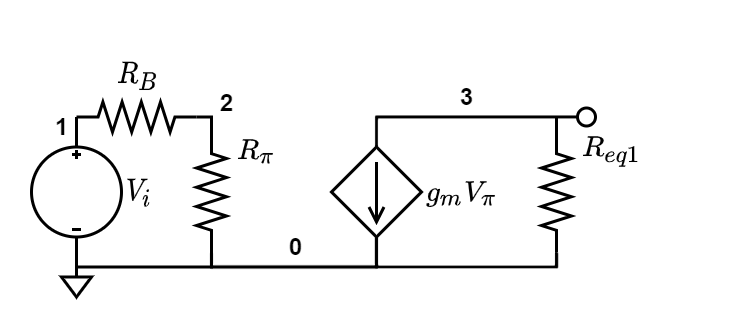

ELAB.analyze(circuit)

Symbolic analysis successful (0.215049 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=V_{i}\\ v_{2}=\frac{R_{\pi ,Q,1}\,V_{i}}{R_{B}+R_{\pi ,Q,1}}\\ v_{3}=\frac{G_{Q,1}\,R_{\mathrm{eq1}}\,R_{\pi ,Q,1}\,V_{i}}{R_{B}+R_{\pi ,Q,1}} \end{array}\right)$$

ELAB.ec2sd(circuit,1,3)

Symbolic transfer function calculated successfully (3.117200e-03 sec).


$$ans = \frac{v_{3}}{v_{1}}=\frac{G_{Q,1}\,R_{\mathrm{eq1}}\,R_{\pi ,Q,1}}{R_{B}+R_{\pi ,Q,1}}$$

circuit = Circuit('circuits/bjt_cs_amp.txt');

ans =     'Vi 0 1 AC Vi
     RB 1 2 RB
     RC 3 0 RC
     R_pi_Q1 2 0 R_pi_Q1
     R_o_Q1 3 0 R_o_Q1
     R_mu_Q1 2 3 R_mu_Q1
     C_pi_Q1 2 0 C_pi_Q1
     C_mu_Q1 2 3 C_mu_Q1
     G_Q1 3 0 0 2 
     '


ELAB.hybrid_pi(circuit,'hf');
hf_circuit.list

### 2. MOSFETs

All the same functionality exists for circuits containing MOSFET transistors. To illustrate this, we load in this circuit.

circuit = Circuit('circuits/mos_cs_amp.txt');
circuit.list

ans =     'V_i 1 0 AC V_i
     V_DD 3 0 DC V_DD
     R_D 2 3 R_D
     R_G 1 2 R_G
     R_L 2 0 R_L
     M_1 1 2 0 100
     '


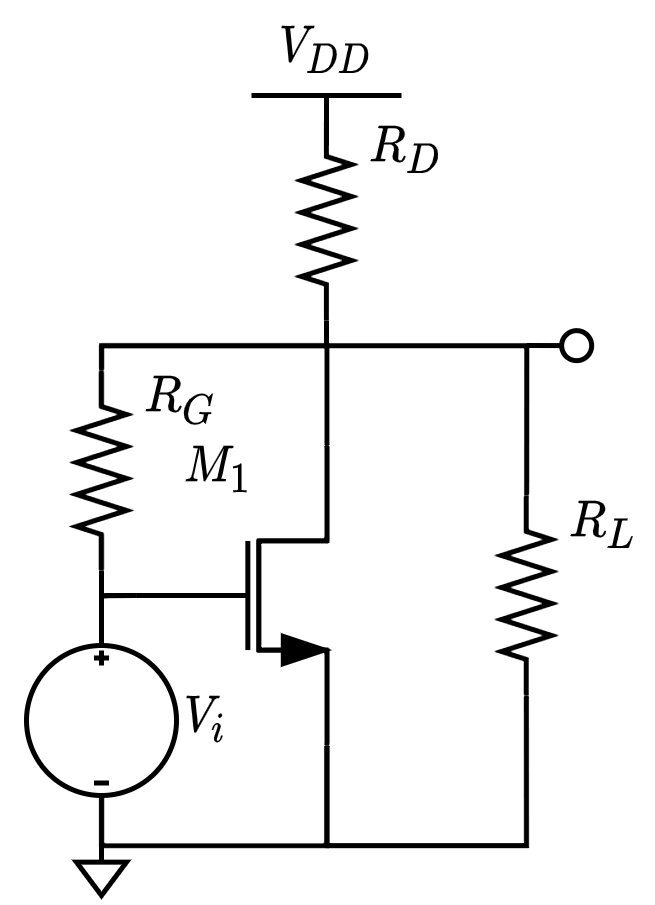

ELAB.hybrid_pi(circuit,'lf');
circuit.list

ans =     'V_i 1 0 AC V_i
     R_D 2 0 R_D
     R_G 1 2 R_G
     R_L 2 0 R_L
     R_o_M_1 2 0 R_o_M_1
     G_M_1 2 0 0 1 G_M_1
     '


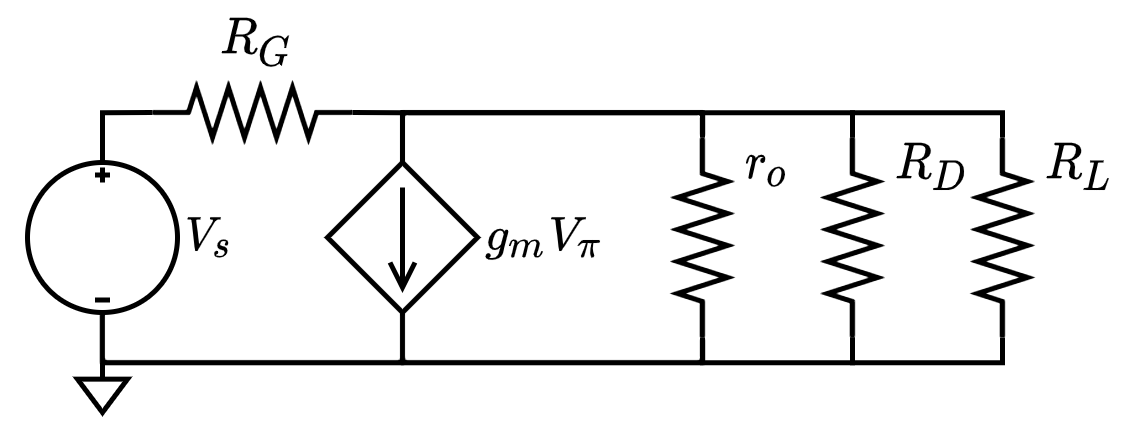

As this circuit contains three resistors in parallel, we may want to simplify the circuit for further analysis.

ELAB.simplify(circuit);
circuit.list

ans =     'V_i 1 0 AC V_i
     R_G 1 2 R_G
     R_eq1 2 0 (R_D*R_L*R_o_M_1)/(R_D*R_L+R_D*R_o_M_1+R_L*R_o_M_1)
     G_M_1 2 0 0 1 G_M_1
     '


ELAB.analyze(circuit)

Symbolic analysis successful (0.189481 sec).


ELAB.ec2sd(circuit,1,2)

Symbolic transfer function calculated successfully (4.169300e-03 sec).


$$ans = \frac{v_{2}}{v_{1}}=\frac{R_{\mathrm{eq1}}\,\left(G_{M,1}\,R_{G}+1\right)}{R_{G}+R_{\mathrm{eq1}}}$$